clear all
clc

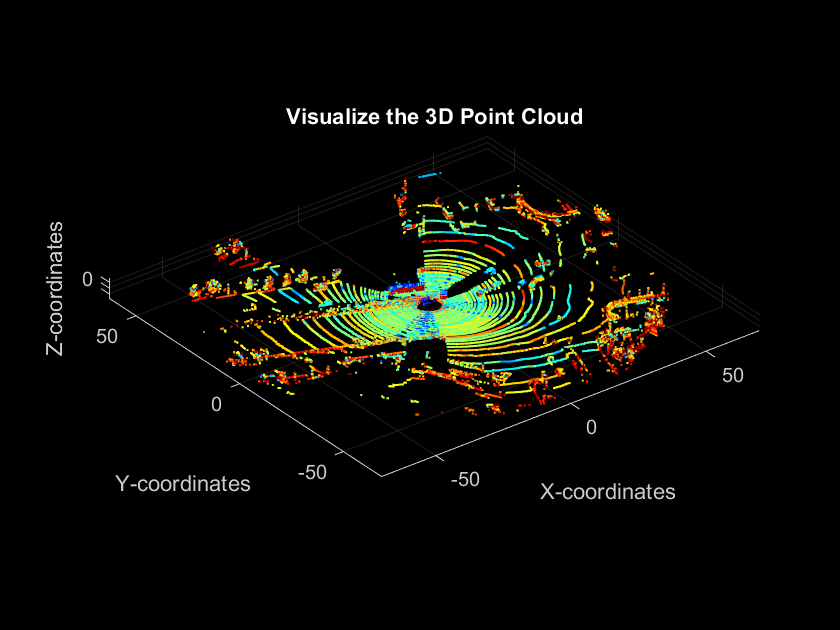

% Q1 Parse the file and visualize the 3D point cloud of this frame.
% Colored by its reflectivity value.

A = fopen('002_00000000.bin');    % Read the one frame from sample set
data = fread(A,'float32');

% Spatial X, Y and Z 3D coordinates of each point
X = [];                           
Y = [];
Z = [];

% Reflectance value of the point
I = [];

for j = 1:4:length(data)       
    X = [X,data(j)];           % X-coordinates
end
for i= 2:4:length(data)
    Y = [Y,data(i)];           % Y-coordinates
end
for i = 3:4:length(data)
    Z = [Z,data(i)];           % Z-coordinates
end
for i = 4:4:length(data)
    I = [I,data(i)];           % Array of reflectance value.
end


figure(1)

cloudpoint = pointCloud([X(:),Y(:),Z(:)],'Intensity',I(:));
pcshow(cloudpoint);
title('Visualize the 3D Point Cloud')
xlabel('X-coordinates')
ylabel('Y-coordinates')
zlabel('Z-coordinates')
xlim('auto')
ylim('auto')
zlim('auto')

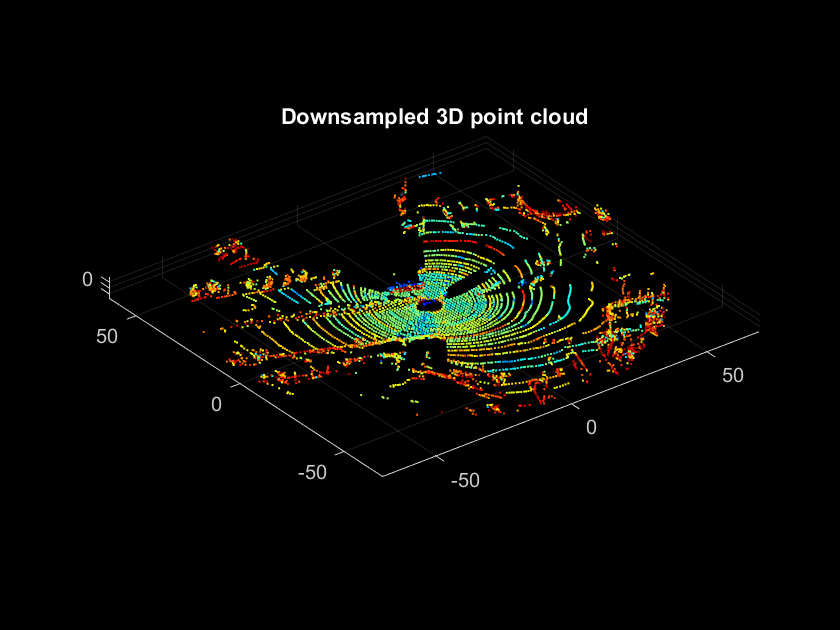

% Q2 Down-sample all the 3D point cloud points to the 3D voxel space points

figure(2)
gridStep = 1.0;                                               % Divided into grid boxes of the size specified by gridStep
voxCloud = pcdownsample(cloudpoint,'gridAverage',gridStep);   % Box grid filter for downsampling
pcshow(voxCloud)
title('Downsampled 3D point cloud');

% Q 3
% This function uses the M-estimator SAmple Consensus (MSAC) algorithm to find the plane. 
% The MSAC algorithm is a variant of the RANdom SAmple Consensus (RANSAC) algorithm.

tic

maxDistance = 0.2;                  % Set the maximum point-to-plane distance (2cm) for plane fitting
referenceVector = [0,0,1];          % Set the normal vector of the plane
maxAngularDistance = 0.7;             % Set the maximum angular distance

[model1,inlierIndices,outlierIndices] = pcfitplane(voxCloud, maxDistance,referenceVector,maxAngularDistance);
plane1 = select(voxCloud,inlierIndices);
remainPtCloud = select(voxCloud,outlierIndices);

toc       % Elapsed time gives the time complexity of the RANSAC algorithm 

Elapsed time is 0.562585 seconds.


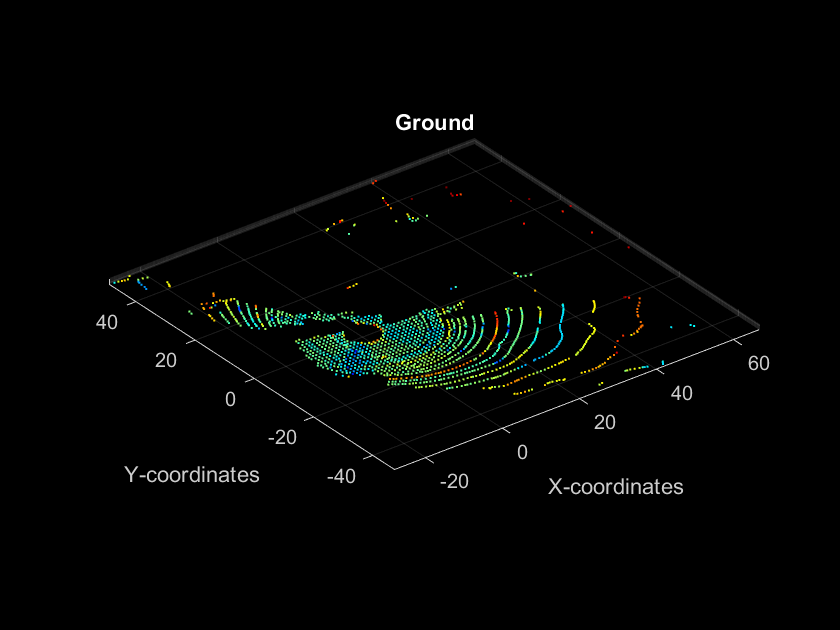


figure(3)
pcshow(plane1)
title('Ground')
xlabel('X-coordinates')
ylabel('Y-coordinates')

hold off

figure(4)
pcshow(plane1)
hold on
plot(model1)
title('Visualize the plane with the points in the 3D')
xlabel('X-coordinates')
ylabel('Y-coordinates')


% Print out your plane model parameter values
model_parameters = model1.Parameters

model_parameters =     0.0115    0.0031    0.9999    1.5514


fprintf('%.4f', model_parameters)

0.01150.00310.99991.5514

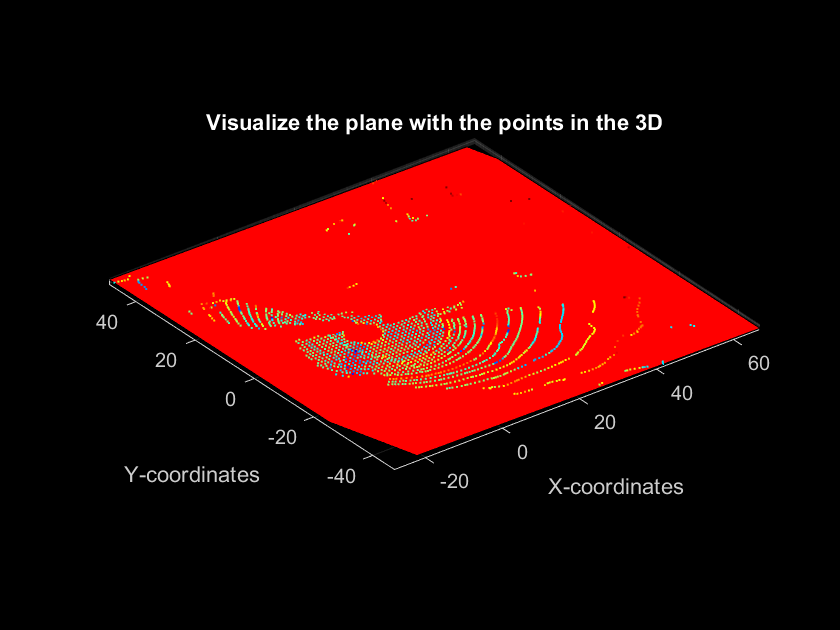


hold off

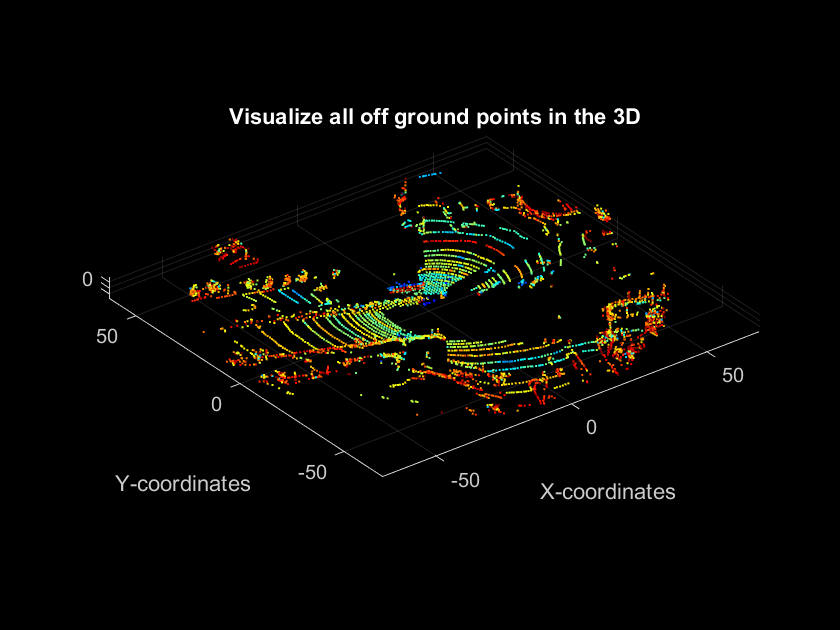


% Q 3c

maxDistance = 0.2;                  % Set the maximum point-to-plane distance (2cm) for plane fitting
referenceVector = [0,0,1];          % Set the normal vector of the plane
maxAngularDistance = 0.7;             % Set the maximum angular distance

[model2,inlierIndices,outlierIndices] = pcfitplane(voxCloud, maxDistance,referenceVector,maxAngularDistance);
remainPtCloud = select(voxCloud,outlierIndices,"OutputSize",'full');
figure(5)
pcshow(remainPtCloud)
title('Visualize all off ground points in the 3D')
xlabel('X-coordinates')
ylabel('Y-coordinates')

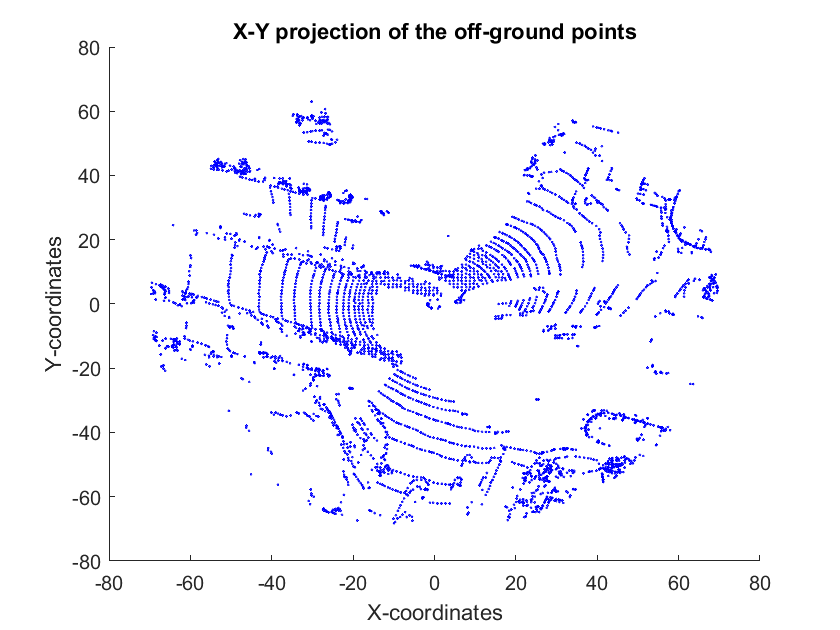

% Q4 Perform a x-y projection to the off-ground points, and get a 2D matrix

x_projection = remainPtCloud.Location(:,1);
y_projection = remainPtCloud.Location(:,2);

matrix_2D = [x_projection, y_projection];

figure(6)
scatter(x_projection,y_projection,1,'blue')
title('X-Y projection of the off-ground points')
xlabel('X-coordinates')
ylabel('Y-coordinates')
hold off

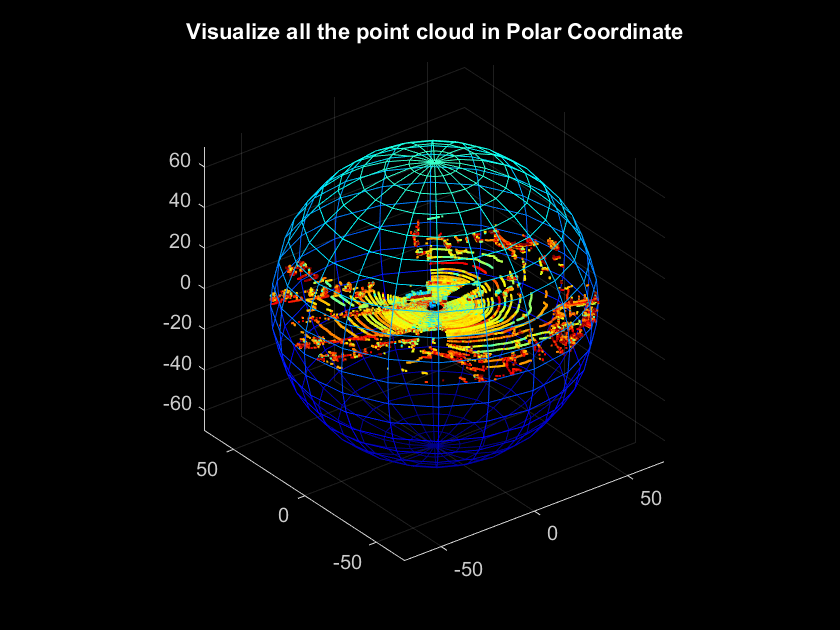

% Q5 Cartesian Coordinate, represent and visualize all the point cloud in Polar Coordinate

x = cloudpoint.Location(:,1);
y = cloudpoint.Location(:,2);
z = cloudpoint.Location(:,3);
in = cloudpoint.Intensity(:);

% Represent points in Polar coordinates
[azimuth,elevation,r] = cart2sph(x,y,z);
matrix =[x,y,z];
figure(7);
[x1, y1, z1] = sphere;
% 70 as this is highest limit in X and Y direction
mesh(70*x1,70*y1,70*z1, 'Marker', 'None','EdgeColor', 'flat',"FaceColor","none")
hold on
plot3(0,0,0)
hold on
pcshow(cloudpoint)
title('Visualize all the point cloud in Polar Coordinate')
hold off

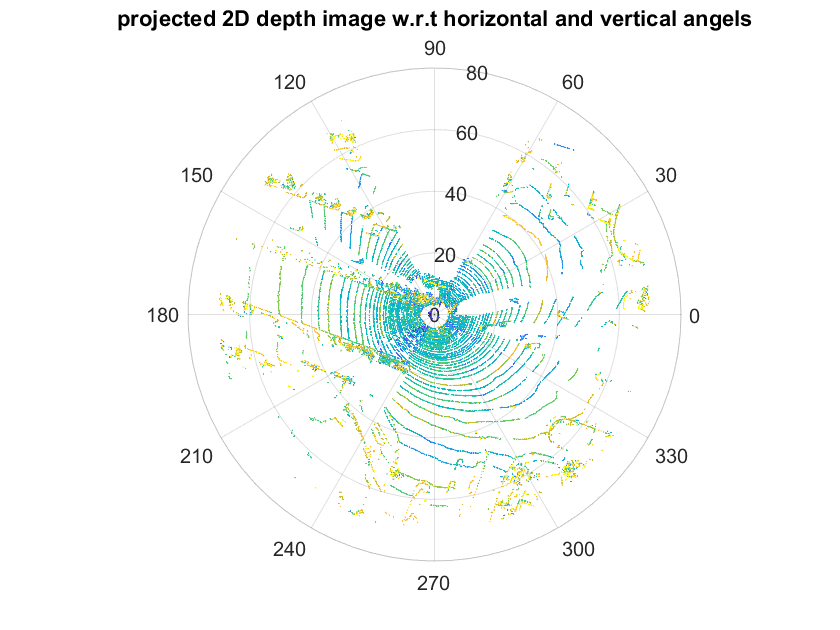

% Q 5b Generate the projected 2D depth image w.r.t horizontal and vertical angels, with intensity value using the distance.

x1 = cloudpoint.Location(:,1);
y1 = cloudpoint.Location(:,2);
z1 = cloudpoint.Location(:,3);
in1 = cloudpoint.Intensity(:);

matrix1 =[x1,y1,z1];
[azimuth1,elevation1,r1]= cart2sph(x1,y1,z1); 
[azimuth, ele, a3] = sph2cart(azimuth1,elevation1,r1);
figure(8)
polarplot= polarscatter(azimuth1,r1,0.1,in1);
set(gca,'color',[1,1,1])
title('projected 2D depth image w.r.t horizontal and vertical angels')